% Parameters
Amplitude = 2;             % Amplitude in V
Frequency = 60;            % freq in Hz
Phase = 0;                 % Phase in radians
Duration = -0.1:0.0001:0.1; % Time vector from -0.1 s to 0.1 s
omega = 2 * pi * Frequency; % Angular frequency

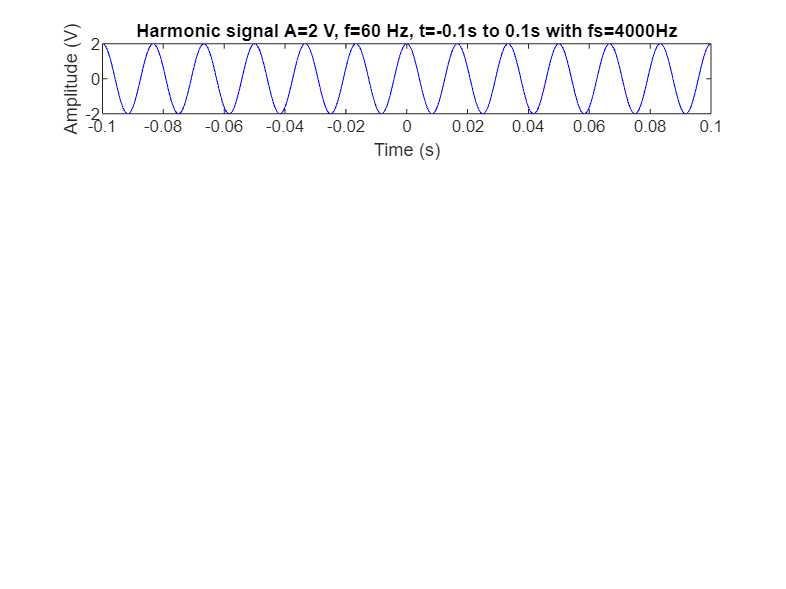

figure;

% Subplot 1: Sampling frequency fs = 4000 Hz
fs1 = 4000;
t1 = -0.1:1/fs1:0.1; % Time vector for fs = 4000 Hz
signal1 = Amplitude * cos(omega * t1 + Phase);
subplot(4,1,1); % subplot
plot(t1, signal1, 'b');
title('Harmonic signal A=2 V, f=60 Hz, t=-0.1s to 0.1s with fs=4000Hz');
xlabel('Time (s)');
ylabel('Amplitude (V)');

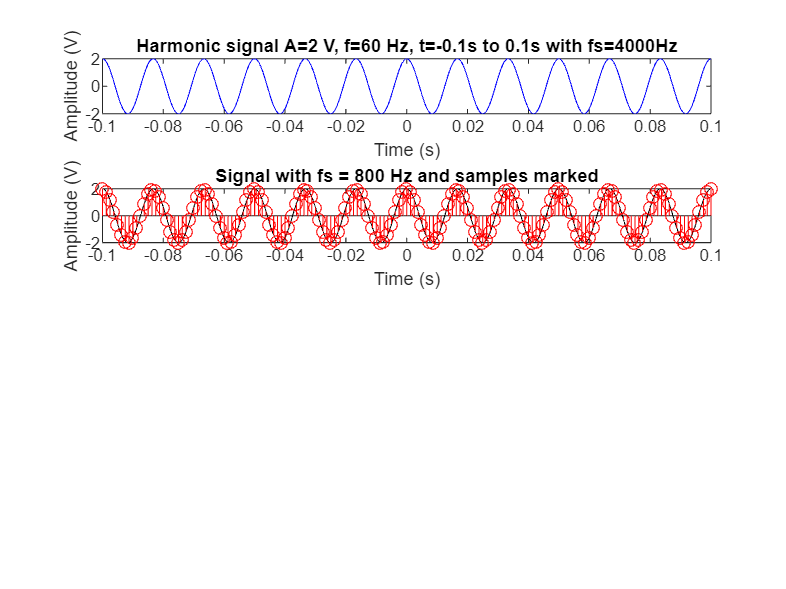

% Subplot 2: Sampling frequency fs = 800 Hz
fs2 = 800;
t2 = -0.1:1/fs2:0.1; % Time vector for fs = 800 Hz
signal2 = Amplitude * cos(omega * t2 + Phase);
subplot(4,1,2); % Create subplot
plot(Duration, Amplitude * cos(omega * Duration + Phase), 'k'); hold on;
stem(t2, signal2, 'r');
title('Signal with fs = 800 Hz and samples marked');
xlabel('Time (s)');
ylabel('Amplitude (V)');

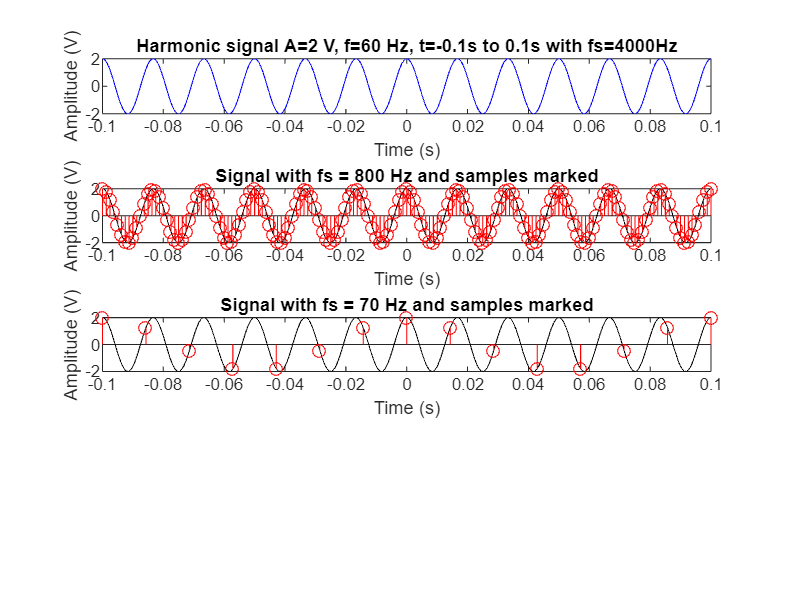

% Subplot 3: Sampling frequency fs = 70 Hz
fs3 = 70;
t3 = -0.1:1/fs3:0.1; % Time vector for fs = 70 Hz
signal3 = Amplitude * cos(omega * t3 + Phase);
subplot(4,1,3); % Create a subplot
plot(Duration, Amplitude * cos(omega * Duration + Phase), 'k'); hold on;
stem(t3, signal3, 'r');
title('Signal with fs = 70 Hz and samples marked');
xlabel('Time (s)');
ylabel('Amplitude (V)');

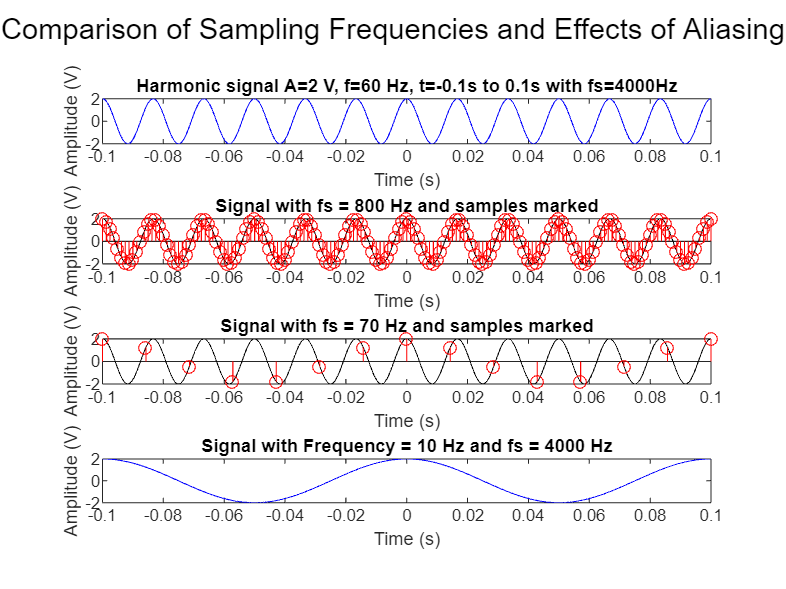

% Subplot 4: Different frequency and fs = 4000 Hz
Frequency2 = 10;
omega2 = 2 * pi * Frequency2; % Angular frequency for 10 Hz
t4 = -0.1:1/fs1:0.1; % Time vector for fs = 4000 Hz
signal4 = Amplitude * cos(omega2 * t4 + Phase);
subplot(4,1,4); % Create a subplot
plot(t4, signal4, 'b');
title('Signal with Frequency = 10 Hz and fs = 4000 Hz');
xlabel('Time (s)');
ylabel('Amplitude (V)');

sgtitle('Comparison of Sampling Frequencies and Effects of Aliasing');

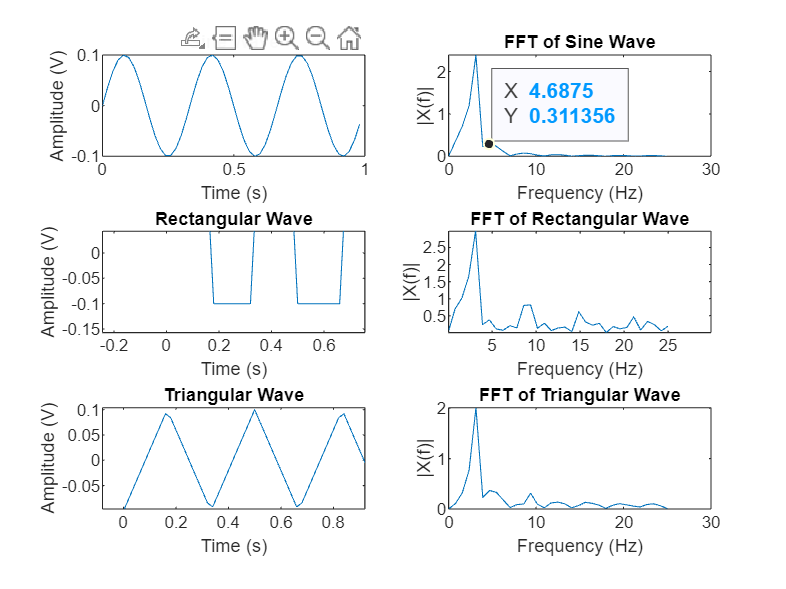

% Parameters
Amplitude = 0.1;        % Amplitude of the signals
Frequency = 3;          % Frequency of the signals
Fs = 50;                % Sampling frequency
T = 1/Fs;               % Sampling period
L = Fs;                 % Length of signal (1 second duration)
t = (0:L-1)*T;          % Time vector

% 1. Sinusoidal signal
sin_signal = Amplitude * sin(2*pi*Frequency*t);

% 2. Rectangular signal
rect_signal = Amplitude * square(2*pi*Frequency*t);

% 3. Triangular signal
tri_signal = Amplitude * sawtooth(2*pi*Frequency*t, 0.5);

% Compute FFT
n = 2^nextpow2(L);
fft_sin = fft(sin_signal, n);
fft_rect = fft(rect_signal, n);
fft_tri = fft(tri_signal, n);
f = Fs*(0:(n/2))/n;

% Plotting Time Domain Signals
figure;
subplot(3,2,1);
plot(t, sin_signal);
title('Sine Wave');
xlabel('Time (s)');
ylabel('Amplitude (V)');

subplot(3,2,3);
plot(t, rect_signal);
title('Rectangular Wave');
xlabel('Time (s)');
ylabel('Amplitude (V)');

subplot(3,2,5);
plot(t, tri_signal);
title('Triangular Wave');
xlabel('Time (s)');
ylabel('Amplitude (V)');

% Plotting Frequency Domain Signals
subplot(3,2,2);
plot(f, abs(fft_sin(1:n/2+1)));
title('FFT of Sine Wave');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');

subplot(3,2,4);
plot(f, abs(fft_rect(1:n/2+1)));
title('FFT of Rectangular Wave');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');

subplot(3,2,6);
plot(f, abs(fft_tri(1:n/2+1)));
title('FFT of Triangular Wave');
xlabel('Frequency (Hz)');
ylabel('|X(f)|');